# CUE Plots

#### CUE dynamics against residual MCPA in soils, and temporal CUE dynamics

## Calling Data

load('residual.txt')
load('CUE.txt')

## Calling model parameters

load('model_parameters_hierarchy.mat')

## Running models

% (20, 1.8, 20°)
s = 6;
[mineralD,transcriptsD,DNA_totD,P_totalD1,C_14_minD1,tspanD1,CUE_G1,CUE_E1,CUE_M1,CUE_T1,CUE_ET1,CUE_EM1,CUE_EG1] = plotting_hierarchy_file(p,s);

% (20, 3.5, 20°)
s = 8;
[mineralD,transcriptsD,DNA_totD,P_totalD2,C_14_minD2,tspanD2,CUE_G2,CUE_E2,CUE_M2,CUE_T2,CUE_ET2,CUE_EM2,CUE_EG2] = plotting_hierarchy_file(p,s);

% (20, 1.8, 10°)
s = 2;
[mineralD,transcriptsD,DNA_totD,P_totalD3,C_14_minD3,tspanD3,CUE_G3,CUE_E3,CUE_M3,CUE_T3,CUE_ET3,CUE_EM3,CUE_EG3] = plotting_hierarchy_file(p,s);

% (20, 3.5, 10°)
s = 4;
[mineralD,transcriptsD,DNA_totD,P_totalD4,C_14_minD4,tspanD4,CUE_G4,CUE_E4,CUE_M4,CUE_T4,CUE_ET4,CUE_EM4,CUE_EG4] = plotting_hierarchy_file(p,s);

% (1, 1.8, 20°)
s = 5;
[mineralD,transcriptsD,DNA_totD,P_totalD5,C_14_minD5,tspanD5,CUE_G5,CUE_E5,CUE_M5,CUE_T5,CUE_ET5,CUE_EM5,CUE_EG5] = plotting_hierarchy_file(p,s);

% (1, 3.5, 20°)
s = 7;
[mineralD,transcriptsD,DNA_totD,P_totalD6,C_14_minD6,tspanD6,CUE_G6,CUE_E6,CUE_M6,CUE_T6,CUE_ET6,CUE_EM6,CUE_EG6] = plotting_hierarchy_file(p,s);

% (1, 1.8, 10°)
s = 1;
[mineralD,transcriptsD,DNA_totD,P_totalD7,C_14_minD7,tspanD7,CUE_G7,CUE_E7,CUE_M7,CUE_T7,CUE_ET7,CUE_EM7,CUE_EG7] = plotting_hierarchy_file(p,s);

% (1, 3.5, 10°)
s = 3;
[mineralD,transcriptsD,DNA_totD,P_totalD8,C_14_minD8,tspanD8,CUE_G8,CUE_E8,CUE_M8,CUE_T8,CUE_ET8,CUE_EM8,CUE_EG8] = plotting_hierarchy_file(p,s);

## CUE_s - concepts

#### CUE_E = CUE Identical to the calculated based on experimental data


$$        CUE_E = \displaystyle\frac{^{14}C_B}{^{14}C_B + ^{14}CO_2} 
$$


#### CUE_T = CUE Considering microbial turnover


$$        CUE_T = 1 -  \displaystyle\frac{r^{14}_{respiration}+r^{14}_{m-endogenous}+r^{14}_{m-exogenous}+r^{NER}_{decay}}{r^{14}_{respiration}+r^{14}_{growth}+r^{14}_{m-exogenous}} $$


## CUE_E vs. Normalized residual MCPA in soils

% 20 mg/Kg, pF 1.8 %

disp('CUE_E - 20 mg - pF 1.8')

CUE_E - 20 mg - pF 1.8


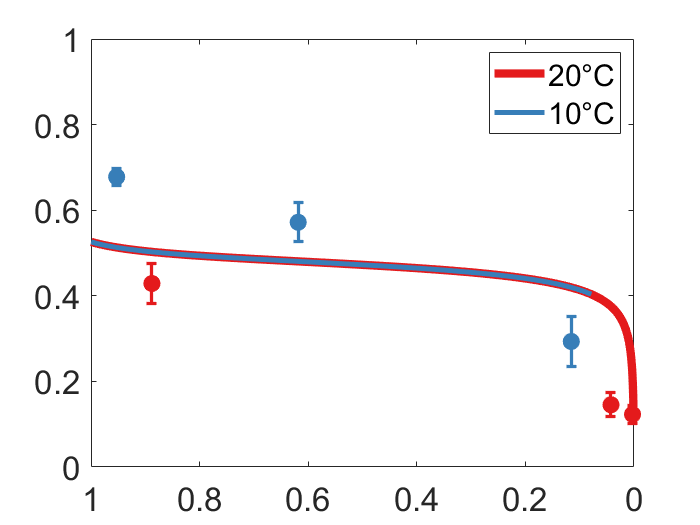


figure('Name','CUE_E_1')
A1 = plot(P_totalD1*(1000*200/9)/20,CUE_E1,'LineWidth',5,'color',[228,26,28,140]/255); 
hold on
err = CUE(16:18,6);
E   = errorbar(vertcat(residual(27,5),residual(29:30,5))/20,CUE(16:18,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A3  = plot(P_totalD3*(1000*200/9)/20,CUE_E3,'LineWidth',3,'color',[55,126,184,140]/255); 
err = CUE(13:15,6);
E   = errorbar(vertcat(residual(7,5),residual(9:10,5))/20,CUE(13:15,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
set(gca, 'Xdir', 'reverse')
ylim([0 1])
hold off
legend([A1 A3],{'20°C','10°C'})


% 20 mg/Kg, pF 3.5 %

disp('CUE_E - 20 mg - pF 3.5')

CUE_E - 20 mg - pF 3.5


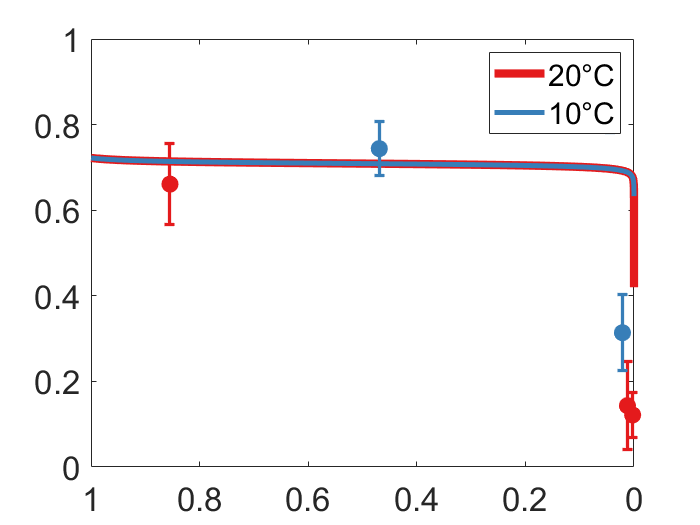

figure('Name','CUE_E_2')
A2  = plot(P_totalD2*(1000*200/9)/20,CUE_E2,'LineWidth',5,'color',[228,26,28,140]/255); 
hold on
err = CUE(22:24,6);
E   = errorbar(vertcat(residual(37,5),residual(39:40,5))/20,CUE(22:24,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A4  = plot(P_totalD4*(1000*200/9)/20,CUE_E4,'LineWidth',3,'color',[55,126,184,140]/255);
err = CUE(19:21,6);
E   = errorbar(vertcat(residual(17,5)/20,residual(19:20,5))/20,CUE(19:21,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
set(gca, 'Xdir', 'reverse')
ylim([0 1])
hold off
legend([A2 A4],{'20°C','10°C'})


% 1 mg/Kg, pF 1.8 %

disp('CUE_E - 1 mg - pF 1.8')

CUE_E - 1 mg - pF 1.8


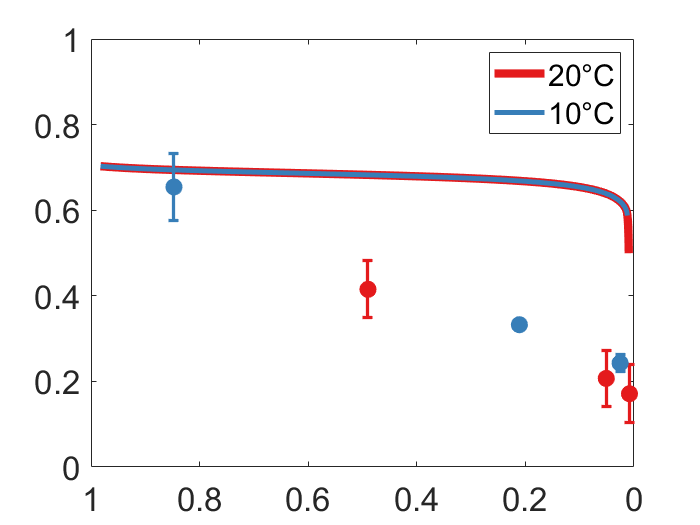

figure('Name','CUE_E_1')
A5 = plot(P_totalD5*(1000*200/9)/1,CUE_E5,'LineWidth',5,'color',[228,26,28,140]/255); 
hold on
err = CUE(4:6,6);
E   = errorbar(vertcat(residual(22,5),residual(24:25,5))/1,CUE(4:6,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A7 = plot(P_totalD7*(1000*200/9)/1,CUE_E7,'LineWidth',3,'color',[55,126,184,140]/255); 
err = CUE(1:3,6);
E   = errorbar(vertcat(residual(2,5),residual(4:5,5))/1,CUE(1:3,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
ylim([0 1])
set(gca, 'Xdir', 'reverse')
hold off
legend([A5 A7],{'20°C','10°C'})


% 1 mg/Kg, pF 3.5 %

disp('CUE_E - 1 mg - pF 3.5')

CUE_E - 1 mg - pF 3.5


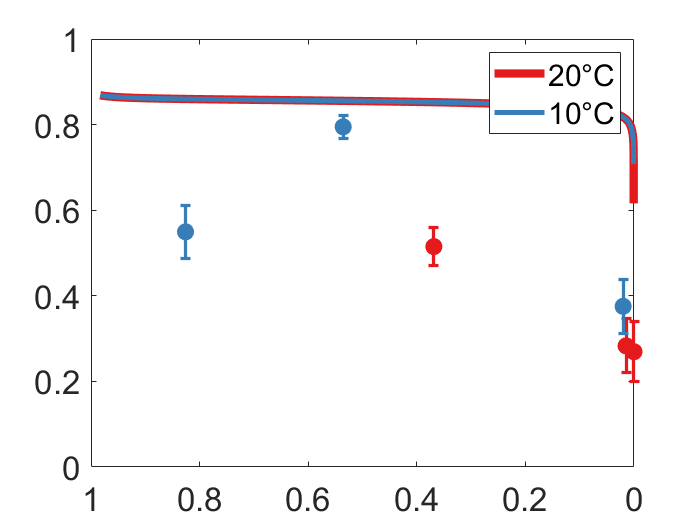

figure('Name','CUE_E_2')
A6 = plot(P_totalD6*(1000*200/9)/1,CUE_E6,'LineWidth',5,'color',[228,26,28,140]/255);
hold on
err = CUE(10:12,6);
E   = errorbar(vertcat(residual(32,5),residual(34:35,5))/1,CUE(10:12,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A8 = plot(P_totalD8*(1000*200/9)/1,CUE_E8,'LineWidth',3,'color',[55,126,184,140]/255); 
err = CUE(7:9,6);
E   = errorbar(vertcat(residual(12,5),residual(14:15,5))/1,CUE(7:9,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
ylim([0 1])
set(gca, 'Xdir', 'reverse')
hold off
legend([A6 A8],{'20°C','10°C'}) 

## CUE_T vs. Normalized residual MCPA in soils

% 20 mg/Kg, pF 1.8 %

disp('CUE_C - 20 mg - pF 1.8')

CUE_C - 20 mg - pF 1.8


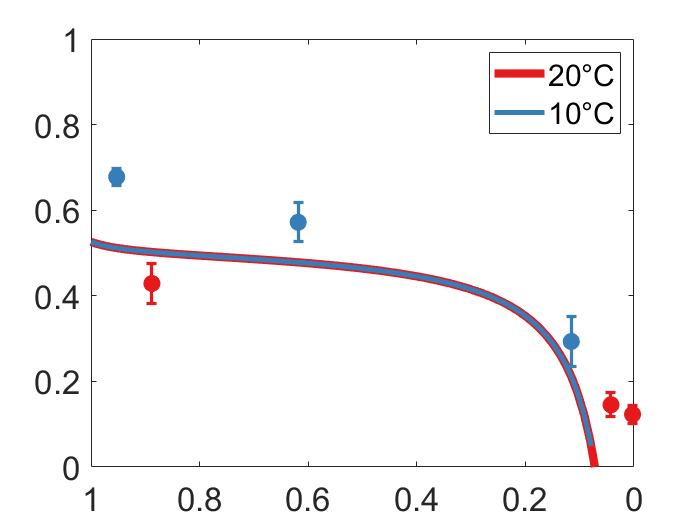


figure('Name','CUE_T_1')
A1 = plot(P_totalD1*(1000*200/9)/20,CUE_T1,'LineWidth',5,'color',[228,26,28,140]/255); 
hold on
err = CUE(16:18,6);
E   = errorbar(vertcat(residual(27,5),residual(29:30,5))/20,CUE(16:18,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A3  = plot(P_totalD3*(1000*200/9)/20,CUE_T3,'LineWidth',3,'color',[55,126,184,140]/255); 
err = CUE(13:15,6);
E   = errorbar(vertcat(residual(7,5),residual(9:10,5))/20,CUE(13:15,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
set(gca, 'Xdir', 'reverse')
ylim([0 1])
hold off
legend([A1 A3],{'20°C','10°C'})


% 20 mg/Kg, pF 3.5 %

disp('CUE_C - 20 mg - pF 3.5')

CUE_C - 20 mg - pF 3.5


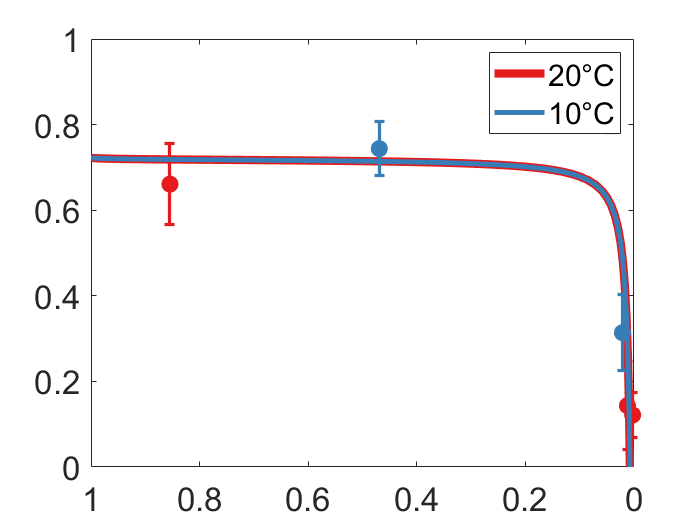


figure('Name','CUE_T_2')
A2  = plot(P_totalD2*(1000*200/9)/20,CUE_T2,'LineWidth',5,'color',[228,26,28,140]/255); 
hold on
err = CUE(22:24,6);
E   = errorbar(vertcat(residual(37,5),residual(39:40,5))/20,CUE(22:24,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A4  = plot(P_totalD4*(1000*200/9)/20,CUE_T4,'LineWidth',3,'color',[55,126,184,140]/255);
err = CUE(19:21,6);
E   = errorbar(vertcat(residual(17,5)/20,residual(19:20,5))/20,CUE(19:21,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
set(gca, 'Xdir', 'reverse')
ylim([0 1])
hold off
legend([A2 A4],{'20°C','10°C'})


% 1 mg/Kg, pF 1.8 %

disp('CUE_C - 1 mg - pF 1.8')

CUE_C - 1 mg - pF 1.8


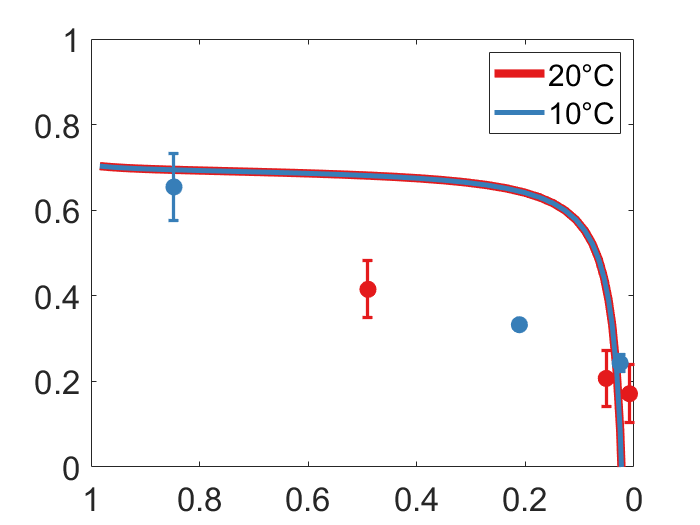


figure('Name','CUE_T_1')
A5 = plot(P_totalD5*(1000*200/9)/1,CUE_T5,'LineWidth',5,'color',[228,26,28,140]/255); 
hold on
err = CUE(4:6,6);
E   = errorbar(vertcat(residual(22,5),residual(24:25,5))/1,CUE(4:6,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A7 = plot(P_totalD7*(1000*200/9)/1,CUE_T7,'LineWidth',3,'color',[55,126,184,140]/255); 
err = CUE(1:3,6);
E   = errorbar(vertcat(residual(2,5),residual(4:5,5))/1,CUE(1:3,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
ylim([0 1])
set(gca, 'Xdir', 'reverse')
hold off
legend([A5 A7],{'20°C','10°C'})


% 1 mg/Kg, pF 3.5 %

disp('CUE_C - 1 mg - pF 3.5')

CUE_C - 1 mg - pF 3.5


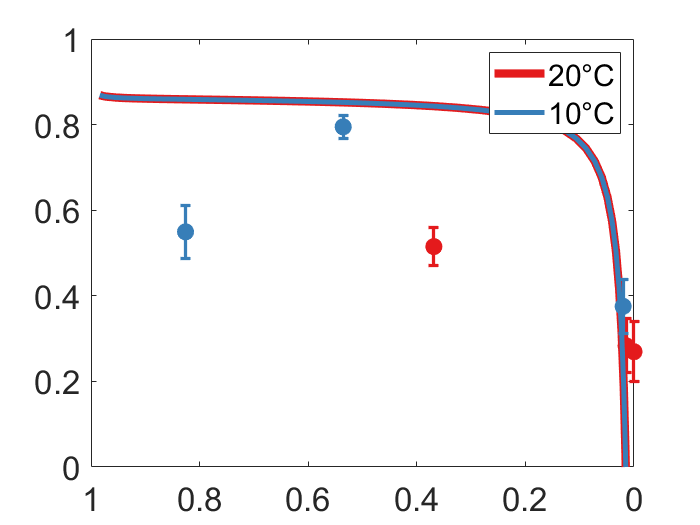


figure('Name','CUE_T_2')
A6 = plot(P_totalD6*(1000*200/9)/1,CUE_T6,'LineWidth',5,'color',[228,26,28,140]/255);
hold on
err = CUE(10:12,6);
E   = errorbar(vertcat(residual(32,5),residual(34:35,5))/1,CUE(10:12,5),err,'.',...
    'MarkerSize',35,'color',[228,26,28,140]/255,'LineWidth',2);
A8 = plot(P_totalD8*(1000*200/9)/1,CUE_T8,'LineWidth',3,'color',[55,126,184,140]/255); 
err = CUE(7:9,6);
E   = errorbar(vertcat(residual(12,5),residual(14:15,5))/1,CUE(7:9,5),err,'.',...
    'MarkerSize',35,'color',[55,126,184,140]/255,'LineWidth',2);
box on
ax = gca;
ax.FontSize = 20;
ylim([0 1])
set(gca, 'Xdir', 'reverse')
hold off
legend([A6 A8],{'20°C','10°C'})